# Exercise 4

## 1. Image Enhancement Intensity Transformation

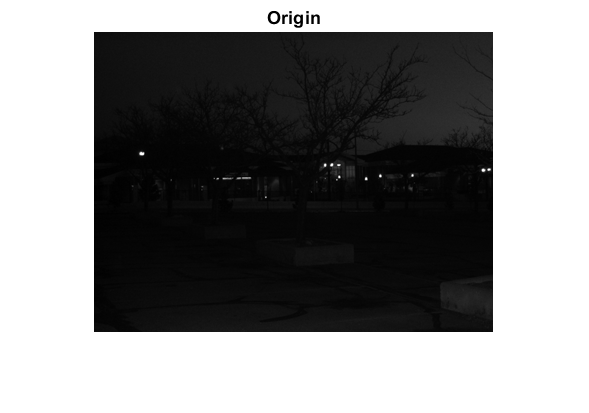

I = imread('university.png');
I=im2double(I);
[m n] = size(I);
figure,imshow(I);title('Origin');

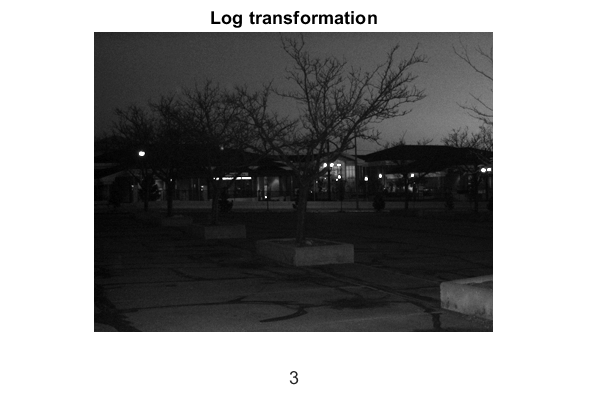

% Compute using log transformation
c = 3;
for p = 1 : m
    for q = 1 : n
        I3(p, q) = c *log(1+ I(p, q));  
    end
end

figure, imshow(I3);title('Log transformation');xlabel('c='),xlabel(c);

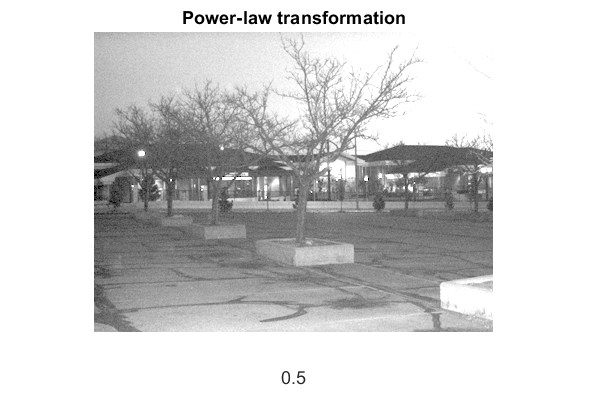


%% Compute using power-law transformation
% computing size m,n 

%%
% Computing s = c * (r ^ gamma) where r and gamma are positive constants 
c = 3;
g = 0.5 ;% Gamma Correction Array
for p = 1 : m
    for q = 1 : n
        I3(p, q) = c * I(p, q).^ g;  
    end
end

figure, imshow(I3);title('Power-law transformation');xlabel('Gamma='),xlabel(g);


% FIX : Can apply these transformation directly to the image, not necessary to 
% each pixel.


## 2. Histogram equalization

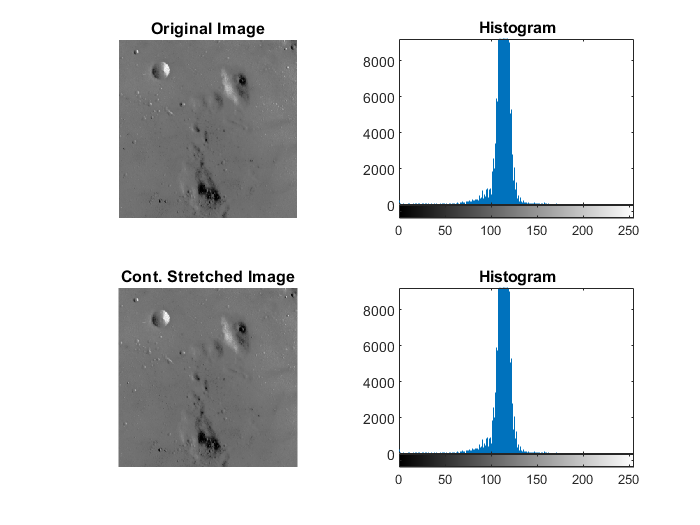

moon = imread('moon.png');
H_moon = histequal(moon);
ContrastStretch(moon,0,255);

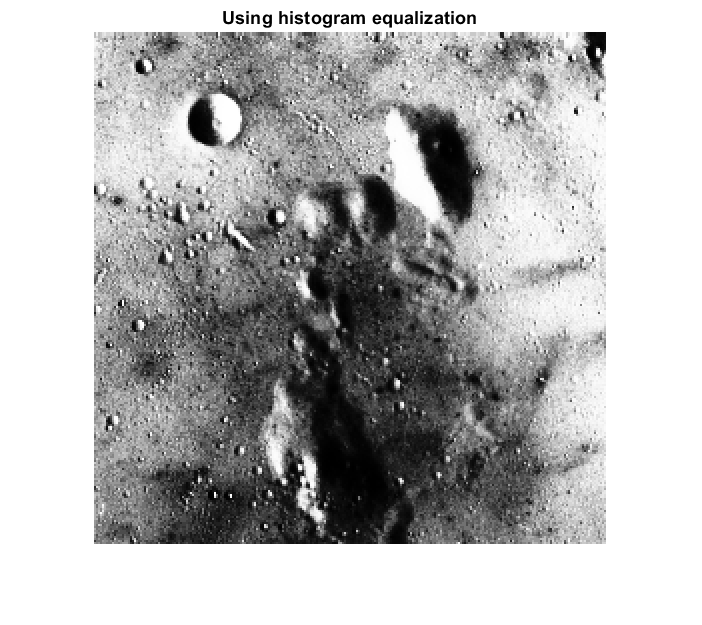

figure,imshow(H_moon),title('Using histogram equalization');

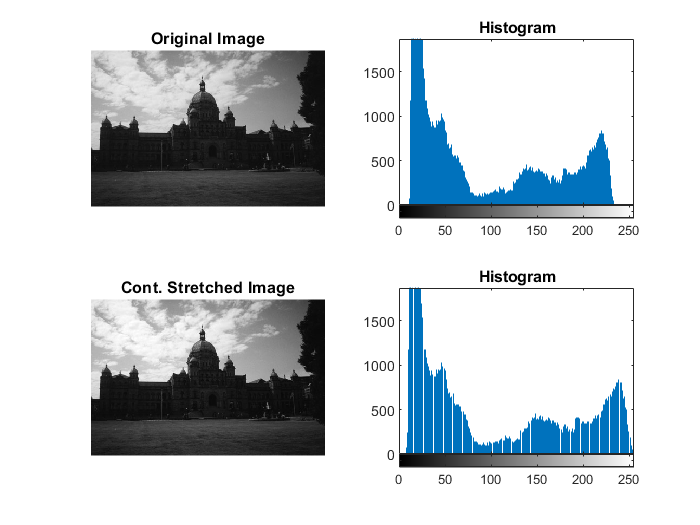


house = imread('house.png');
H_house = histequal(house);
ContrastStretch(house,0,255);

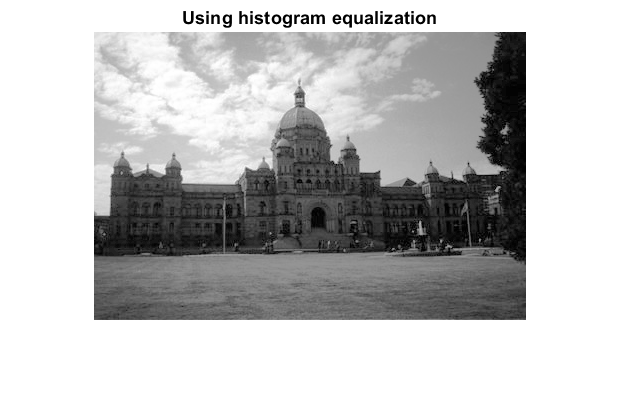

figure,imshow(H_house),title('Using histogram equalization');

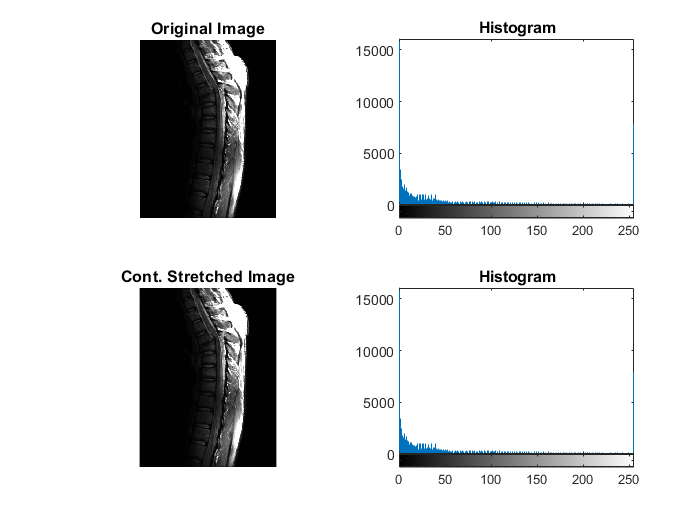



spine= imread('spine.jpg');
H_spine = histequal(spine);
ContrastStretch(spine,0,255);

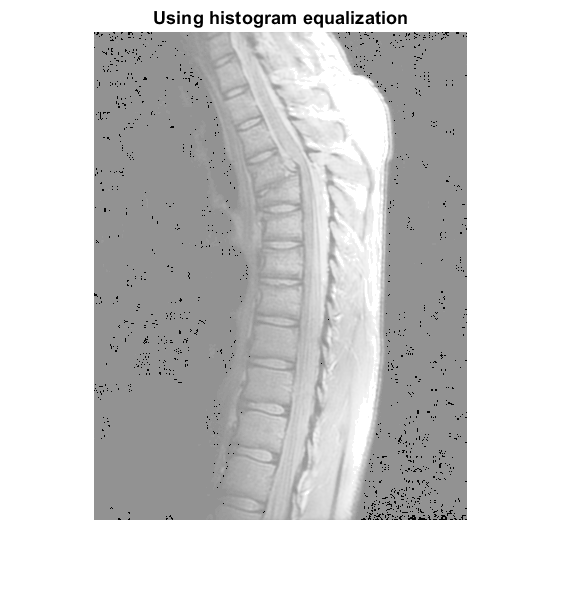

figure,imshow(H_spine),title('Using histogram equalization');

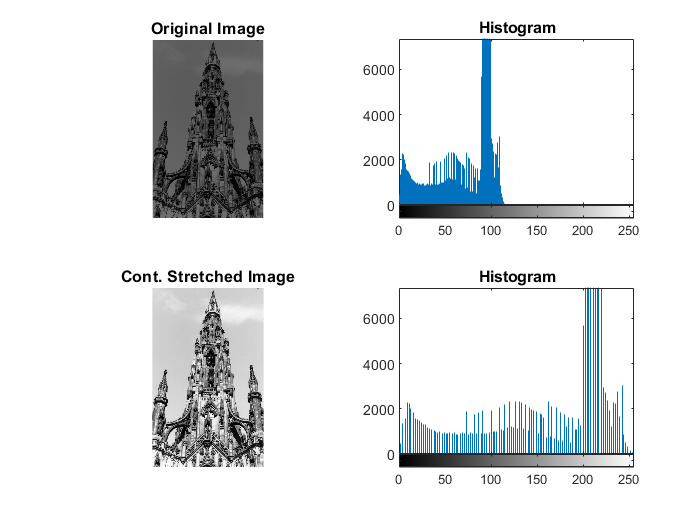


church = imread("church.png");
H_church = histequal(church);

ContrastStretch(church,0,255);

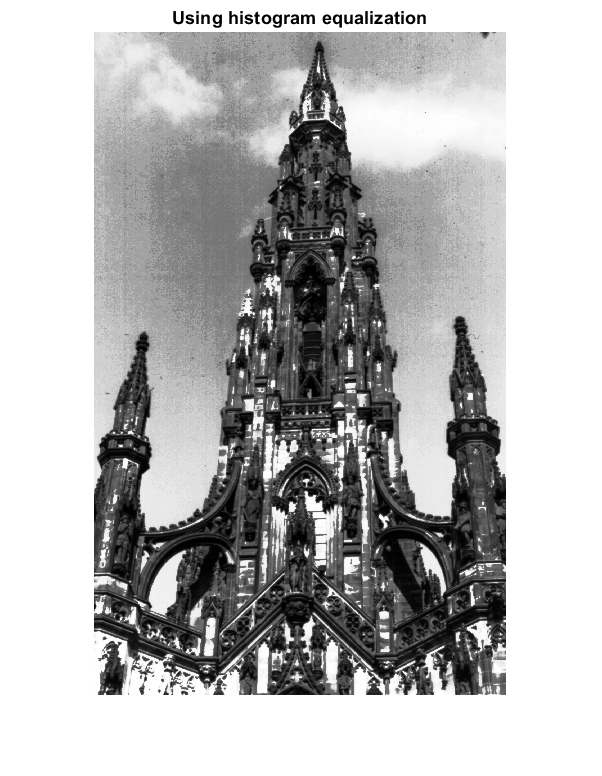

figure,imshow(H_church),title("Using histogram equalization");

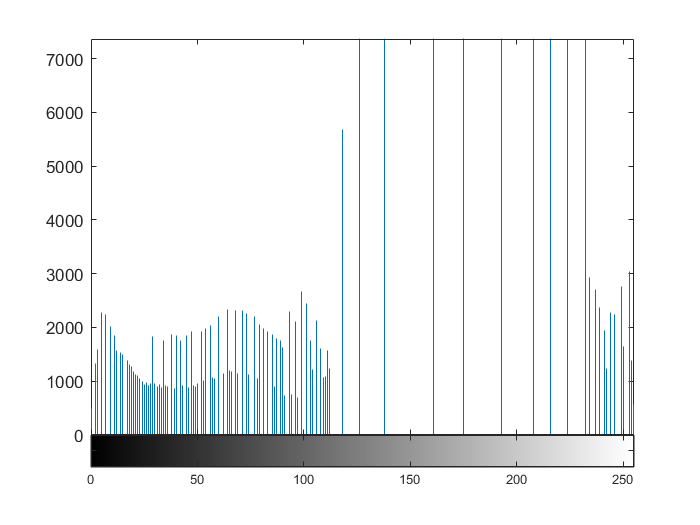

figure,imhist(H_church);

## 3.Histogram matching

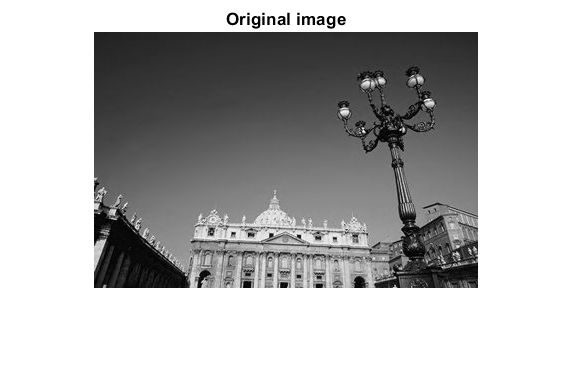

imA = imread('corel.png');
imB1 = imread('spine.jpg');
imB2 = imread('church.png');
imshow(imA);title('Original image');

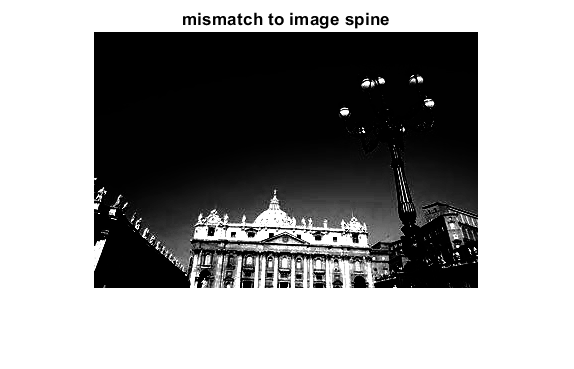

imshow(histmatch(imA,imB1));title('mismatch to image spine');

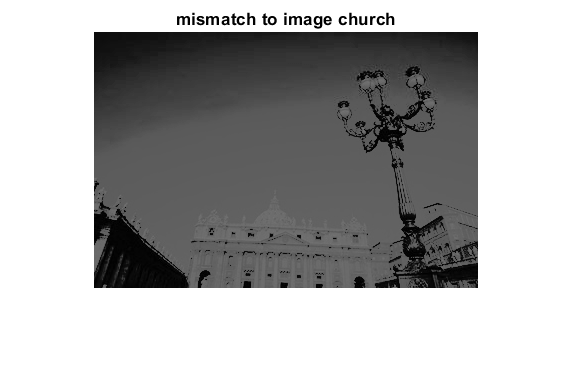

imshow(histmatch(imA,imB2));title('mismatch to image church');

## 4.Properties of Histogram Equalization

a.

Histogram equalization increases the global constrast of the images that have intensity having  close contrast values. This allows for areas of lower local contrast to gain a higher contrast. Histogram equalization accomplishes this by effectively spreading out the most frequent intensity values.

Thus when additional application won't bring additional effects since the distribution of intensity has been wider in histogram.

b.

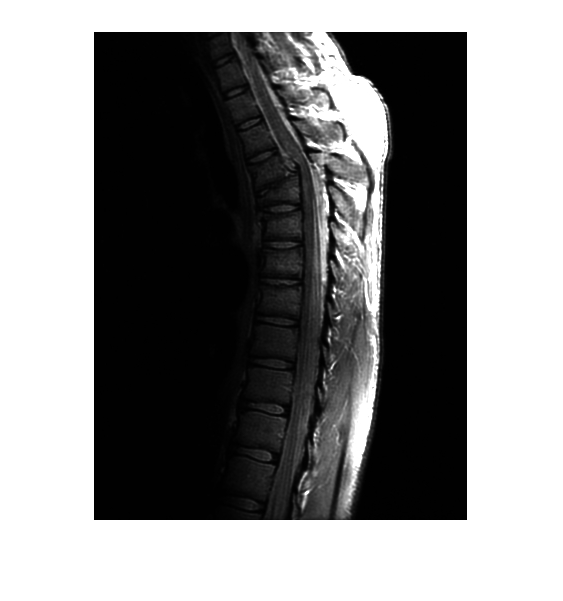

ori = imread('spine.jpg');
figure,imshow(ori);

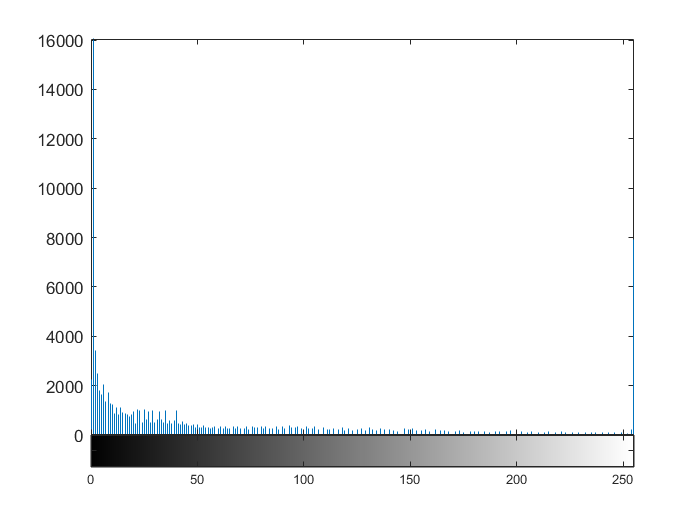

figure,imhist(ori);

figure,imshow(histequal(ori)),title('Using histogram equalization');

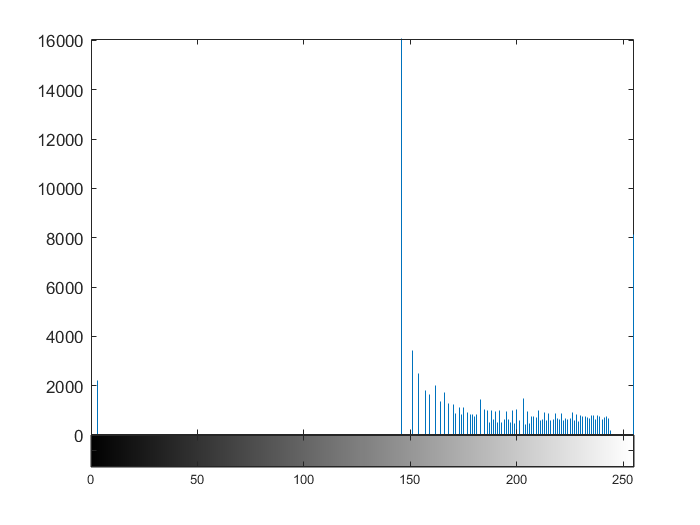

figure,imhist(histequal(ori));

 Alternative method : Divide the image into blocks and apply hist equalization into each blocks (localize histogram equalization)